## Problem 8.2

*Part B* - Find $\mathit{\mathbf{x}}$ such that $\textrm{Ax}=\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$

$\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{-1} \mathit{\mathbf{y}}$, $\mathit{\mathbf{x}}=\left\lbrack \begin{array}{c}
-1\ldotp 0204\\
2\ldotp 0408
\end{array}\right\rbrack$

A = [[1.02 1]; [1 0.99]];
y = [1; 1];
x = A\y;
display(x);

x =    -1.0204
    2.0408


*Part C* - Find $\mathit{\mathbf{x}}$ such that $\textrm{Ax}=\left\lbrack \begin{array}{c}
1\ldotp 1\\
1
\end{array}\right\rbrack$

A small perturbation in $\mathit{\mathbf{y}}$ caused a large perturbation in $\mathit{\mathbf{x}}$! $||{\mathit{\mathbf{y}}}_1 -{\mathit{\mathbf{y}}}_2 ||_2^2 =0\ldotp 01$, $||{\mathit{\mathbf{x}}}_1 -{\mathit{\mathbf{x}}}_2 ||_2^2 =206\ldotp 1745$

A = [[1.02 1]; [1 0.99]];

y1 = [1; 1];
x1 = A\y1;

y2 = [1.1; 1];
x2 = A\y2;

display(x1);

x1 =    -1.0204
    2.0408


display(x2);

x2 =     9.0816
   -8.1633


fprintf("Norm Squared Error in y: %f", norm(y1-y2)^2);

Norm Squared Error in y: 0.010000

fprintf("Norm Squared Error in x: %f", norm(x1-x2)^2);

Norm Squared Error in x: 206.174511

*Part D* - Find the unit vector ${\mathit{\mathbf{e}}}_{\max }$ which maximizes $||\tilde{\mathit{\mathbf{x}}} -\mathit{\mathbf{x}}||_2^2$

We know that the unit eigenvector corresponding with the largest eigenvalue will yield the maximum error, so ${\mathit{\mathbf{e}}}_{\max } =\left\lbrack \begin{array}{c}
0\ldotp 7124\\
0\ldotp 7018
\end{array}\right\rbrack$

*Part E* - Find the unit vector $e_{\min }$ which maximizes $||\tilde{\mathit{\mathbf{x}}} -\mathit{\mathbf{x}}||_2^2$

We know that the unit eigenvector corresponding with the smallest eigenvalue will yield the maximum error, so ${\mathit{\mathbf{e}}}_{\max } =\left\lbrack \begin{array}{c}
-0\ldotp 7018\\
0\ldotp 7124
\end{array}\right\rbrack$

*Part F* - What is the mean-square error $\mathrm{E}\left\lbrack ||\tilde{\mathit{\mathbf{x}}} -\mathit{\mathbf{x}}||_2^2 \right\rbrack$

$\mathrm{E}\left\lbrack ||\tilde{\mathit{\mathbf{x}}} -\mathit{\mathbf{x}}||_2^2 \right\rbrack =\mathrm{E}\left\lbrack ||{\mathit{\mathbf{A}}}^{-1} \mathit{\mathbf{e}}||_2^2 \right\rbrack$ and we know that $E\left\lbrack ||{\mathit{\mathbf{A}}}^{-1} \mathit{\mathbf{e}}||_2^2 \right\rbrack =\sigma^2 \sum_{n=1}^N \frac{1}{\lambda_n^2 }$, so $\mathrm{E}\left\lbrack ||\tilde{\mathit{\mathbf{x}}} -\mathit{\mathbf{x}}||_2^2 \right\rbrack =41816\ldotp 3$

P*art G* - Confirm the solution to *F* with a 10,000 realizations of e

The average error is very close to 41650. See below.

A = [[1.02 1]; [1 0.99]];
y = [1; 1];
x = A\y;

error = 0;
for i = 1:10000
    x_hat = A\(y-randn(2,1));
    error = error + norm(x-x_hat)^2;
end

fprintf("Avg Error: %f", error / 10000);

Avg Error: 41947.623875

## Problem 8.3

*Part A *- Write a matlab function that uses the power iteration procedure to find the largest eigenvalue of matrix A and its associated eigenvalue

function [lambda, v, it] = pm_eig(A)
    sz = size(A);
    sz(2) = 1;
    
    z = ones(sz);
    q = z / norm(z);
    q_prev = zeros(sz);
    it = 0;
    while norm(q-q_prev) > eps && norm(q-q_prev) < 2.0 - eps
        q_prev = q;
        z = A*q_prev;
        q = z / norm(z);
        it = it + 1;
        norm(q-q_prev);
        if it > 1e5
            break
        end
    end
    
    v = q;
    lambda = q.'*A*q;
end

sizes = [10, 100, 1000];

for idx = 1:3
    B = randn([sizes(idx), sizes(idx)]);
    A = B + B.';
    [l, v, i] = pm_eig(A);
    eigs = eig(A);
    eigs = [eigs(1), eigs(end)];
    [~, x] = max(abs(eigs));
    fprintf("%i x %i Matrix", sizes(idx), sizes(idx));
    fprintf("\tMax Eigenvalue (Power Method): %f", l);
    fprintf("\tMax Eigenvalue (Matlab eig): %f", eigs(x));
    fprintf("\tIterations %i\n", i);
end

10 x 10 Matrix

	Max Eigenvalue (Power Method): -5.740534

	Max Eigenvalue (Matlab eig): -5.740534

	Iterations 489


100 x 100 Matrix

	Max Eigenvalue (Power Method): -27.891215

	Max Eigenvalue (Matlab eig): -27.891215

	Iterations 666


1000 x 1000 Matrix

	Max Eigenvalue (Power Method): -89.162418

	Max Eigenvalue (Matlab eig): -89.162418

	Iterations 3089


*Part C* - The number of iterations increases as the matrix size increases. This makes sense, as the power method requires more iterations to converge when the largest and second-largest eigenvalues are close in value. The larger a matrix becomes, the more eigenvalues it has, so there are more opportunities to for $|\lambda_1 |$ and $|\lambda_2 |$ be similar values.

*Part B - *My code and matlab's eig function return the same largest eigenvalues. See a sample output from the above code:

`10 x 10 Matrix`

`	Max Eigenvalue (Power Method): 8.839135`

`	Max Eigenvalue (Matlab eig): 8.839135`

`	Iterations 283`

`100 x 100 Matrix`

`	Max Eigenvalue (Power Method): -27.034852`

`	Max Eigenvalue (Matlab eig): -27.034852`

`	Iterations 983`

`1000 x 1000 Matrix`

`	Max Eigenvalue (Power Method): -89.070349`

`	Max Eigenvalue (Matlab eig): -89.070349`

`	Iterations 2198`

## Problem 8.4

function y = svd_reconstruct(x, r)
    [U, S, V] = svd(x);
    y = U(:,1:r)*S(1:r,1:r)*V(:,1:r).';
end

*Part A* - Dispay ${\mathit{\mathbf{A}}}_{\mathit{\mathbf{s}}}$ for $s=\left\lbrack 500,200,100,30,10\right\rbrack$

A = double(imread("flower.png"));
A0 = svd_reconstruct(A, 50);

image(A); 

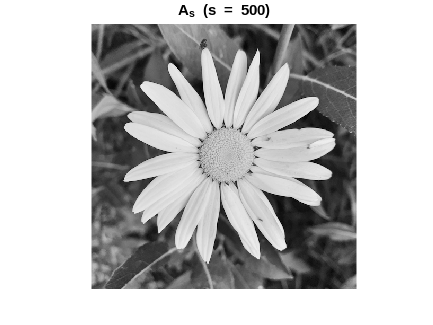

colormap("gray"); 
axis square;
axis off; 
title("A_s (s = 500)");

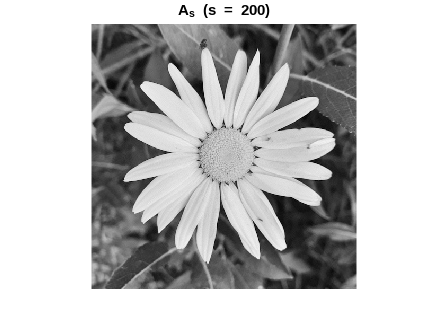


image(uint8(svd_reconstruct(A, 200))); 
colormap("gray"); 
axis square;
axis off;
title("A_s (s = 200)");

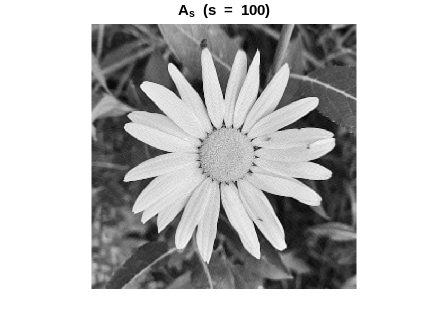


image(uint8(svd_reconstruct(A, 100))); 
colormap("gray"); 
axis square;
axis off;
title("A_s (s = 100)");

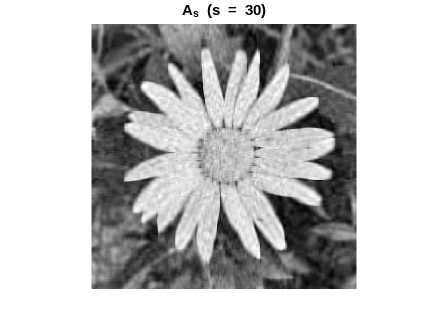


image(uint8(svd_reconstruct(A, 30))); 
colormap("gray"); 
axis square;
axis off;
title("A_s (s = 30)");

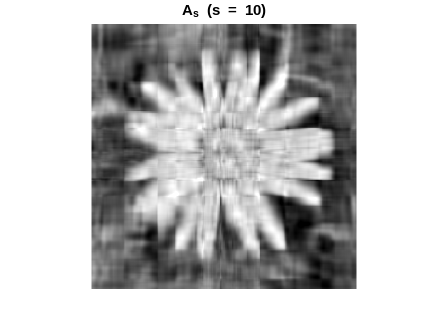


image(uint8(svd_reconstruct(A, 10))); 
colormap("gray"); 
axis square;
axis off;
title("A_s (s = 10)");

*Part B* - How many values are required to represent ${\mathit{\mathbf{A}}}_{\mathit{\mathbf{s}}}$ when $s\not= 500$?

${\mathit{\mathbf{u}}}_{s\;} \in {\mathbb{R}}^{500\;x\;S}$, ${\mathit{\mathbf{v}}}_s^T \in {\mathbb{R}}^{S\;x\;500}$, and $\sigma_s$ has $s$ non-zero values, therefore, the SVD representation with $s$ singular values has $2\left(500\times s\right)+s$ values.

s = [200, 100, 30, 10];

for idx = 1:4
    vals = 500 * s(idx) * 2 + s(idx);
    fprintf("Number of values to represent A with %i sv's: %i\n", s(idx), vals);
end

Number of values to represent A with 200 sv's: 200200
Number of values to represent A with 100 sv's: 100100
Number of values to represent A with 30 sv's: 30030
Number of values to represent A with 10 sv's: 10010
